# Plotting Electricity Stats by Year and Month

Instructions are in the task pane to the left. Complete and submit each task one at a time.

This code sets up the activity.

electricity = readtable("../data/electricity.csv"); 

electricity = electricity(1:find(electricity.Date=='12/01/2015'), :);
com = reshape(electricity.Commercial, 12, []);
res = reshape(electricity.Residential, 12, []);
ind = reshape(electricity.Industrial, 12, []);

usage = ind + res + com;
yr = 1990:2015;

## Task 1

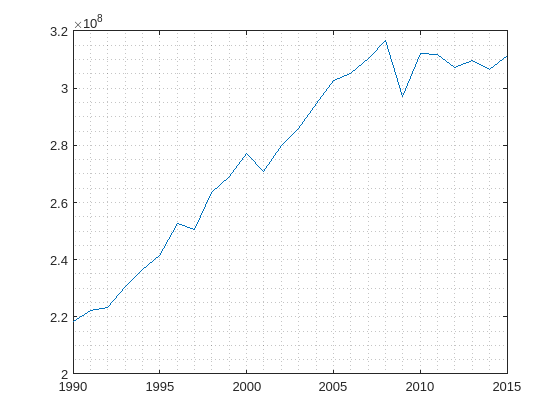

annual = mean(usage, "omitnan");
plot(yr, annual)
grid minor

## Task 2

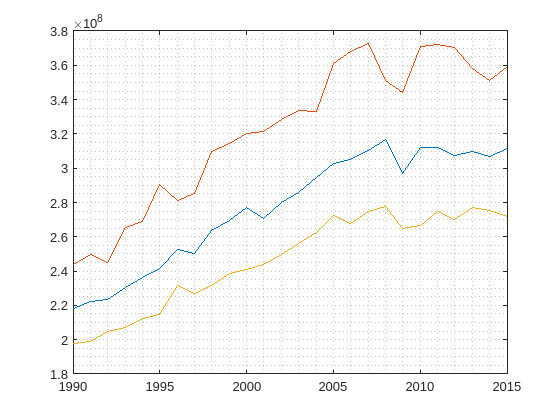

hold on
plot(yr, max(usage))
plot(yr, min(usage))
hold off

## Task 3

monthly = mean(usage, 2, "omitnan")

monthly = 1.0e+08 *

    2.8323
    2.6639
    2.6223
    2.4484
    2.5771
    2.8644
    3.1466
    3.2060
    2.9731
    2.6327


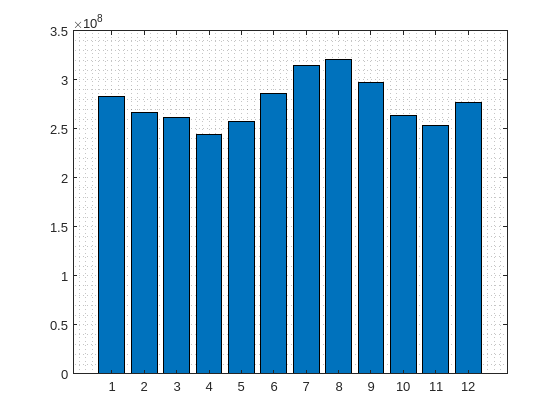

bar(monthly)
grid minor

## Task 4

maxUsage = max(usage, [], 2)

maxUsage =    333405189
   308241264
   302045432
   277152264
   296373214
   330240674
   370333559
   372691410
   329450326
   307130995


minUsage = min(usage, [], 2)

minUsage =    231033219
   206016978
   206723722
   197909489
   200580649
   219185276
   242999824
   243728457
   236200203
   214119000


## Task 5

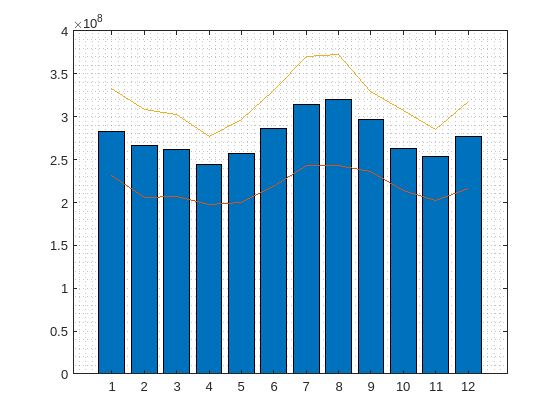

hold on
plot(minUsage)
plot(maxUsage)
hold off

## Task 6

avgUse = mean(usage, "all", "omitnan")

avgUse = 2.7700e+08

minUse = min(usage, [], "all")

minUse = 197909489

maxUse = max(usage, [], "all")

maxUse = 372691410